# Atividade 3  - Série Exponencial de Fourier 

23.01078-9 João Victor Pessoa de Lima dos Anjos

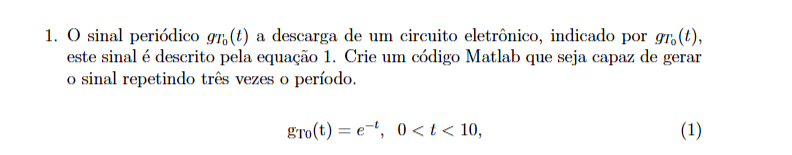

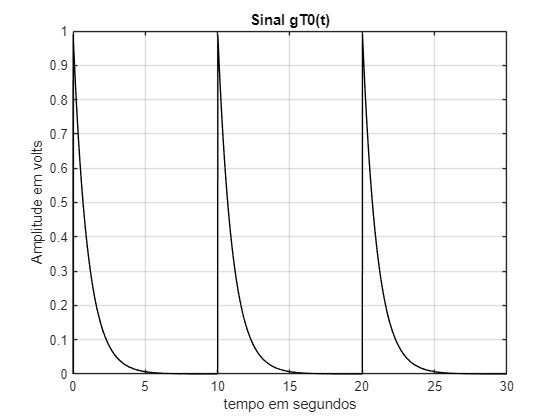

clear;
clc;
close all;

% Parâmetros
T0 = 10;           
num_periodos = 3;   
total_time = T0 * num_periodos; % Tempo total 
dt = 0.01;         % Passo de tempo para discretização
t = 0:dt:total_time; % Vetor de tempo de 0 a 30 segundos

% Inicializar o sinal periódico
g_T0 = zeros(size(t)); % Vetor para armazenar o sinal

% Gerar o sinal periódico
for i = 1:length(t)
    % Calcular o tempo dentro de um período usando mod (para periodicidade)
    t_mod = mod(t(i), T0);
    % O sinal é e^(-t) no intervalo 0 < t <= T0
    if t_mod == 0 % Para evitar o ponto t_mod = 0 (não está no intervalo 0 < t <= T0)
        g_T0(i) = exp(-T0); % Continuidade no limite
    else
        g_T0(i) = exp(-t_mod);
    end
end

% Plotar o sinal periódico
figure;
plot(t, g_T0, 'k', 'LineWidth', 0.5);
grid on;
xlabel('tempo em segundos');
ylabel('Amplitude em volts');
title('Sinal gT0(t)');
xlim([0 total_time]);

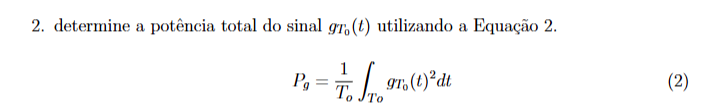

%Calculando a potência pela integral
Pg = (1/T0) * integral(@(t) exp(-2*t), 0, T0);
fprintf('A potência total do sinal gT0(t) é de ~ %.2f W\n ', Pg);

A potência total do sinal gT0(t) é de ~ 0.05 W
 

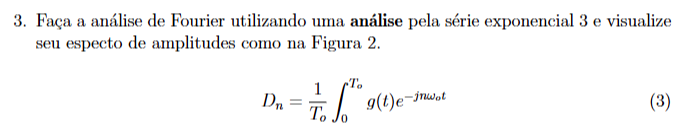

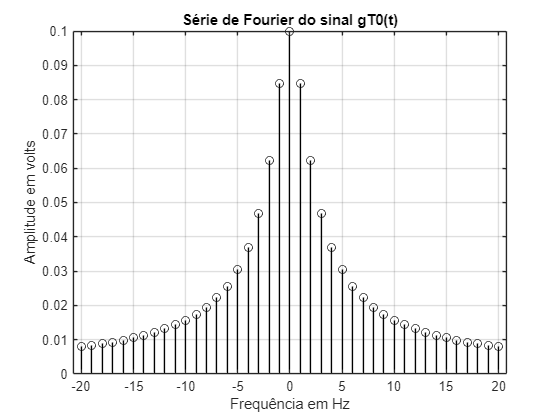

N = 20; % Número de harmônicas
n = -N:N; % Índice da série
w0 = 2*pi/T0; % Frequência fundamental

Dn = zeros(size(n));

for k = 1:length(n)
    nk = n(k);
    Dn(k) = (1/T0) * integral(@(t) exp(-t - 1j*nk*w0*t), 0, T0);
end

figure;
stem(n, abs(Dn), 'k', 'LineWidth', 0.5);
xlabel('Frequência em Hz');
ylabel('Amplitude em volts');
title('Série de Fourier do sinal gT0(t)');
grid on;

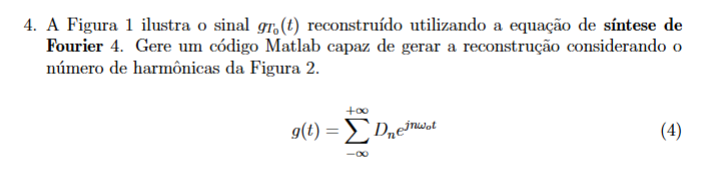

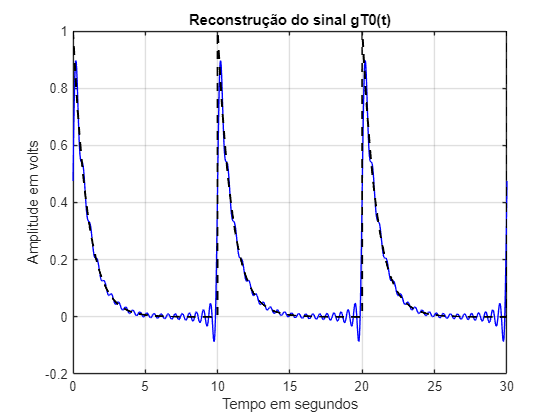

t_rec = 0:0.01:3*T0; % Tempo para três períodos
g_rec = zeros(size(t_rec));

for k = 1:length(n)
    g_rec = g_rec + Dn(k) * exp(1j * n(k) * w0 * t_rec);
end

g_rec = real(g_rec); % ConsideraNDO apenas a parte real

figure;
plot(t_rec, g_rec, 'b-', 'LineWidth', 0.01);
hold on;
plot(t_rec, exp(-mod(t_rec, T0)), 'k--', 'LineWidth', 1.5); % Sinal original para comparação
xlabel('Tempo em segundos');
ylabel('Amplitude em volts');
title('Reconstrução do sinal gT0(t)');
grid on;

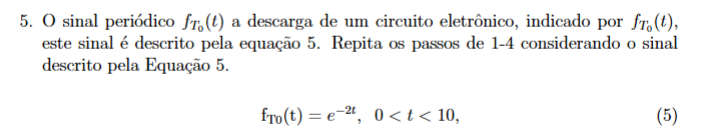

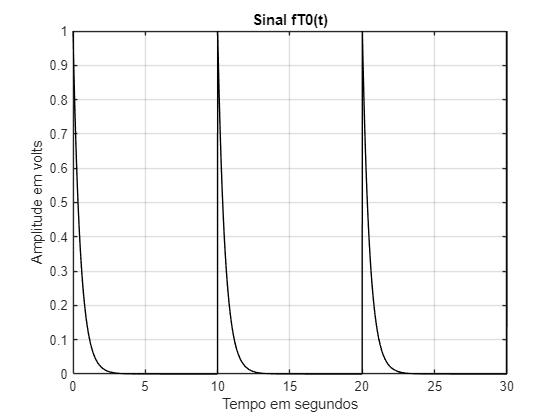


%REFAZENDO OS PASSOS 1 - 4 CONSIDERANDO fT0(t) = e^-2t

% passo 1
T0 = 10; % Período
t = 0:0.01:3*T0; % Intervalo de tempo
fT0 = exp(-2 * mod(t, T0)); % Sinal periódico

figure;
plot(t, fT0, 'k', 'LineWidth', 0.5);
xlabel('Tempo em segundos');
ylabel('Amplitude em volts');
title('Sinal fT0(t)');
grid on;


% passo 2

Pg = (1/T0) * integral(@(t) exp(-4*t), 0, T0);
fprintf('A potência total do sinal fT0(t) é de ~ %.3f W\n ', Pg);

A potência total do sinal fT0(t) é de ~ 0.025 W
 

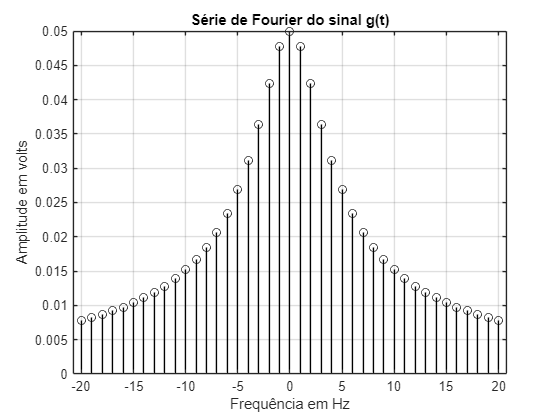


% passo 3
N = 20; % Número de harmônicas
n = -N:N; % Índice da série
w0 = 2*pi/T0; % Frequência fundamental

Dn = zeros(size(n));

for k = 1:length(n)
    nk = n(k);
    Dn(k) = (1/T0) * integral(@(t) exp(-2*t - 1j*nk*w0*t), 0, T0);
end

figure;
stem(n, abs(Dn), 'k', 'LineWidth', 0.5);
xlabel('Frequência em Hz');
ylabel('Amplitude em volts');
title('Série de Fourier do sinal g(t)');
grid on;

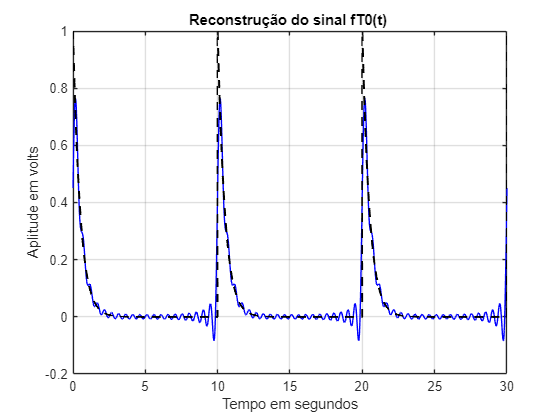


% passo 4
t_rec = 0:0.01:3*T0; 
g_rec = zeros(size(t_rec));

for k = 1:length(n)
    g_rec = g_rec + Dn(k) * exp(1j * n(k) * w0 * t_rec);
end

g_rec = real(g_rec); %Apenas parte real

figure;
plot(t_rec, g_rec, 'b', 'LineWidth', 0.5);
hold on;
plot(t_rec, exp(-2 * mod(t_rec, T0)), 'k--', 'LineWidth', 1.5); % Sinal original para comparação
xlabel('Tempo em segundos');
ylabel('Aplitude em volts');
title('Reconstrução do sinal fT0(t) ');
grid on;

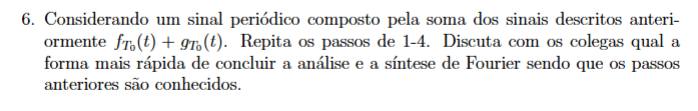

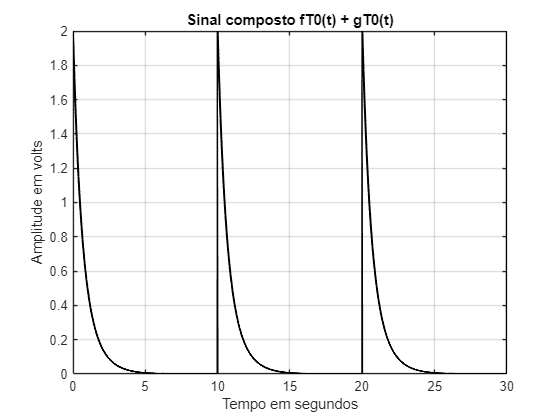



%REFAZENDO OS PASSOS 1 AO 4 CONSIDERANDO SOMA DOS SINAIS fT0(t) + gT0(t):
%e^-t + e^-2t

% passo 1
T0 = 10; 
t = 0:0.01:3*T0; % Tempo para três períodos

% Novo sinal: soma dos sinais anteriores
scomposto = exp(-2 * mod(t, T0)) + exp(-mod(t, T0)); 

figure;
plot(t, scomposto, 'k', 'LineWidth', 1.5);
xlabel('Tempo em segundos');
ylabel('Amplitude em volts');
title('Sinal composto fT0(t) + gT0(t)');
grid on;


% passo 2
Ps = (1/T0) * integral(@(t) (exp(-2*t) + exp(-t)).^2, 0, T0);
fprintf('A potência total do sinal composto gT0(t) + fT0(t) é de ~ %.4f w\n', Ps);

A potência total do sinal composto gT0(t) + fT0(t) é de ~ 0.1417 w


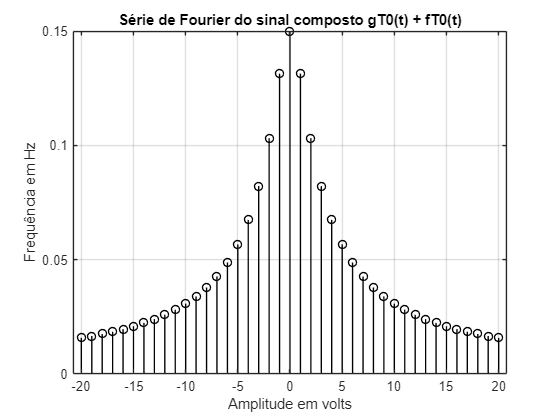


%passo 3

N = 20; % Número de harmônicas
n = -N:N; % Índice da série
w0 = 2*pi/T0; % Frequência fundamental

Dn_s = zeros(size(n));

for k = 1:length(n)
    nk = n(k);
    % Somando os coeficientes dos sinais anteriores
    Dn_f = (1/T0) * integral(@(t) exp(-2*t - 1j*nk*w0*t), 0, T0);
    Dn_g = (1/T0) * integral(@(t) exp(-t - 1j*nk*w0*t), 0, T0);
    Dn_s(k) = Dn_f + Dn_g;
end

figure;
stem(n, abs(Dn_s),'k' , 'LineWidth', 1.0);
xlabel('Amplitude em volts');
ylabel('Frequência em Hz');
title('Série de Fourier do sinal composto gT0(t) + fT0(t)');
grid on;

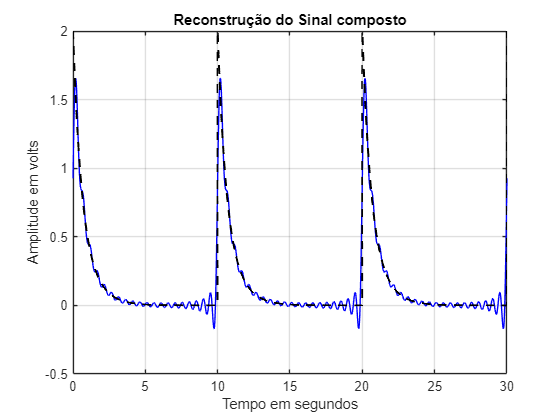


% passo 4

t_rec = 0:0.01:3*T0; 
s_rec = zeros(size(t_rec));

for k = 1:length(n)
    s_rec = s_rec + Dn_s(k) * exp(1j * n(k) * w0 * t_rec);
end

s_rec = real(s_rec); % Utilizando apenas a parte real

figure;
plot(t_rec, s_rec, 'b', 'LineWidth', 0.5);
hold on;
plot(t_rec, exp(-2 * mod(t_rec, T0)) + exp(-mod(t_rec, T0)), 'k--', 'LineWidth', 1.5);
xlabel('Tempo em segundos');
ylabel('Amplitude em volts');
title('Reconstrução do Sinal composto');
grid on;

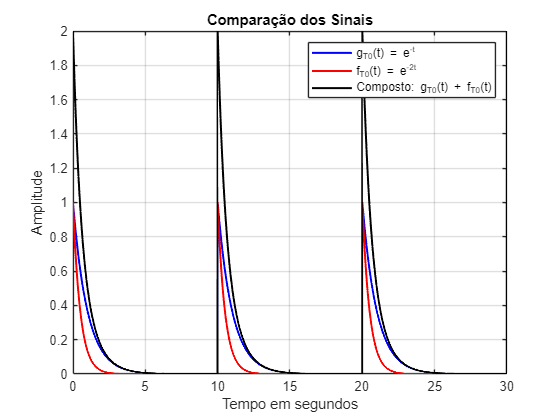



% 3 sinais para avaliação e comparaç,ao

gT0 = exp(-mod(t, T0));
fT0 = exp(-2 * mod(t, T0));
sT0 = gT0 + fT0;
figure;
plot(t, gT0, 'b', 'LineWidth', 1.5); hold on;
plot(t, fT0, 'r', 'LineWidth', 1.5);
plot(t, sT0, 'k', 'LineWidth', 1.5);
xlabel('Tempo em segundos');
ylabel('Amplitude');
title('Comparação dos Sinais');
legend('g_{T0}(t) = e^{-t}', 'f_{T0}(t) = e^{-2t}', 'Composto: g_{T0}(t) + f_{T0}(t)');
grid on;